# Offline RL for GBWM — Week 4 v3: Macro State + Full Train + Multi-Seed

Two changes over week4_macro_state (v2): (A) trainingRange 2000 -> 2515 (full train CSV) and numEpisodes 130 -> 165 so episodes actually cover 2018-Q4 + 2019 rate-hike-then-cut regime. (C) 5 random seeds, full retrain + re-eval per seed; report mean ± std of risk-adjusted metrics across seeds. Everything else (state dim, reward, network, agent options, eval windows) identical to v2 for clean A/B-on-A/B comparison.

clear; clc;

## Fixed Parameters

initialWealth   = 100000;
goalWealth      = 102000;
contribution    = 0;
rebalanceStep   = calmonths(1);

trainingRange   = 2515;       % (A) was 2000, full train CSV now
horizonPeriods  = 30;
numEpisodes     = 165;        % (A) was 130, covers full trainingRange
numActions      = 15;

logsRoot        = fullfile("experiments", "logs", "week4_macro_state_v3");

hiddenUnits     = 32;
maxEpochs       = 100;
stepsPerEpoch   = 400;
miniBatchSize   = 256;
discountFactor  = 0.995;

% (C) Multi-seed
seeds           = [1000 2000 3000 4000 5000];
nSeeds          = numel(seeds);

% Eval
numEvalEpisodes = 30;
evalStepSize    = 30;

## Load price data (shared across seeds)

pricesTT   = readtable("data/prices_train.csv");
assetNames = pricesTT.Properties.VariableNames(2:end);
P_train    = pricesTT{:, 2:end};
R_train    = diff(log(P_train));

R_sub = R_train(1:trainingRange, :);
mu    = mean(R_sub, 1)';
Sigma = cov(R_sub);

p = Portfolio("AssetList", assetNames);
p = setDefaultConstraints(p);
p = setAssetMoments(p, mu, Sigma);
W_frontier = estimateFrontier(p, numActions);

## Load macro data, z-score on train

macroTT   = readtable("data/macro_train.csv");
M_train   = macroTT{:, 2:end};
macroMean = mean(M_train, 1);
macroStd  = std(M_train, 0, 1);
macroStd(macroStd == 0) = 1;
M_train_z = (M_train - macroMean) ./ macroStd;

macroTT

macroTT = 2516×5 table
       Date       DGS10    T10Y2Y    VIXCLS    DFF 
    __________    _____    ______    ______    ____

    2010-01-04    3.85      2.76     20.04     0.12
    2010-01-05    3.77      2.76     19.35     0.12
    2010-01-06    3.85      2.84     19.16     0.12
    2010-01-07    3.85      2.82     19.06      0.1
    2010-01-08    3.83      2.87     18.13     0.11
    2010-01-11    3.85       2.9     17.55     0.11
    2010-01-12    3.74      2.82     18.25     0.11
    2010-01-13     3.8      2.83     17.85     0.11
    2010-01-14    3.76      2.82     17.63     0.11
    2010-01-15     3.7      2.81     17.91     0.12
    2010-01-19    3.73       2.8     17.58     0.13
    2010-01-20    3.68      2.76     18.68     0.13
    2010-01-21    3.62      2.75     22.27     0.12
    2010-01-22    3.62    

## Load + z-score test data once

[R_full, M_test_z] = inputTestData('data/prices_test.csv', 'data/macro_test.csv', ...
                                    macroMean, macroStd);

## Cross-seed result storage

results = struct();
results.successRate     = nan(nSeeds, 1);
results.meanSharpe      = nan(nSeeds, 1);
results.stdSharpe       = nan(nSeeds, 1);
results.meanMaxDD       = nan(nSeeds, 1);
results.stdMaxDD        = nan(nSeeds, 1);
results.meanTermWealth  = nan(nSeeds, 1);
results.p10TermWealth   = nan(nSeeds, 1);
results.p90TermWealth   = nan(nSeeds, 1);
results.minSharpe       = nan(nSeeds, 1);
results.p90MaxDD        = nan(nSeeds, 1);
results.actionHist      = zeros(nSeeds, numActions);

allWealthPathsBySeed = cell(nSeeds, 1);

normalizeWealth = @(w) min(w/goalWealth, 5);
timeFrac        = @(t) t / horizonPeriods;

obsDim = 2 + size(M_train_z, 2);

## Loop over seeds

for sIdx = 1:nSeeds
    seed = seeds(sIdx);
    rng(seed, "twister");

    fprintf("\n========== Seed %d (%d/%d) ==========\n", seed, sIdx, nSeeds);

    seedLogsFolder = fullfile(logsRoot, sprintf("seed_%d", seed));
    if isfolder(seedLogsFolder)
        delete(fullfile(seedLogsFolder, "*.mat"));   % clean previous run
    else
        mkdir(seedLogsFolder);
    end

    % --- Build offline episodes ---
    episodeCount = 0;
    startIdx     = 1;
    stepSize     = floor(horizonPeriods/2);

    while episodeCount < numEpisodes && (startIdx + horizonPeriods - 1) <= size(R_sub,1)
        episodeCount = episodeCount + 1;
        expStruct = repmat(struct("Observation",[],"Action",[],"Reward",[], ...
            "NextObservation",[],"IsDone",[]), horizonPeriods, 1);

        wealth = initialWealth;
        for t = 1:horizonPeriods
            dayIdx   = startIdx + t - 1;
            macroVec = M_train_z(dayIdx, :)';
            obs      = [normalizeWealth(wealth); timeFrac(t); macroVec];

            aIdx = randi(numActions);
            w    = W_frontier(:, aIdx);

            r_tp1      = R_sub(dayIdx, :) * w;
            wealthNext = (wealth + contribution) * (1 + r_tp1);

            reward = log(wealthNext / wealth);
            if t == horizonPeriods && wealthNext >= goalWealth
                reward = reward + 1.0;
            end

            nextDayIdx   = min(dayIdx + 1, size(M_train_z, 1));
            nextMacroVec = M_train_z(nextDayIdx, :)';
            nextObs      = [normalizeWealth(wealthNext); ...
                            timeFrac(min(t+1, horizonPeriods)); ...
                            nextMacroVec];
            isDone       = (t == horizonPeriods);

            expStruct(t).Observation     = {obs};
            expStruct(t).Action          = {aIdx};
            expStruct(t).Reward          = reward;
            expStruct(t).NextObservation = {nextObs};
            expStruct(t).IsDone          = isDone;

            wealth = wealthNext;
        end

        epFile = fullfile(seedLogsFolder, sprintf("loggedData%03d.mat", episodeCount));
        exp = expStruct;
        save(epFile, "exp");
        startIdx = startIdx + stepSize;
    end

    fprintf("  Saved %d episodes (%d transitions)\n", ...
        episodeCount, episodeCount * horizonPeriods);

    % --- File datastore ---
    myReadFcn = @(fname) load(fname, "exp").exp;
    fds = fileDatastore(fullfile(seedLogsFolder, "loggedData*.mat"), ...
                        "ReadFcn", myReadFcn);

    % --- Build fresh agent (random init under this seed) ---
    obsInfo = rlNumericSpec([obsDim 1], Name="GBWMObservation");
    actInfo = rlFiniteSetSpec(1:numActions, Name="AllocationIndex");

    criticLG = layerGraph([
        featureInputLayer(obsInfo.Dimension(1), Name="state")
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(hiddenUnits)
        reluLayer
        fullyConnectedLayer(numActions, Name="Qout")
        ]);

    criticNet = dlnetwork(criticLG);
    critic    = rlVectorQValueFunction(criticNet, obsInfo, actInfo);

    agentOpts = rlDQNAgentOptions( ...
        DiscountFactor=discountFactor, ...
        ExperienceBufferLength=1e6, ...
        MiniBatchSize=miniBatchSize, ...
        TargetUpdateMethod="periodic", ...
        TargetUpdateFrequency=4, ...
        UseDoubleDQN=true);
    agentOpts.CriticOptimizerOptions.LearnRate         = 5e-4;
    agentOpts.CriticOptimizerOptions.GradientThreshold = 1;
    agent = rlDQNAgent(critic, agentOpts);

    % --- Train ---
    tfdOpts = rlTrainingFromDataOptions( ...
        MaxEpochs        = maxEpochs, ...
        NumStepsPerEpoch = stepsPerEpoch, ...
        Plots            = "none", ...               % suppress per-seed plot
        Verbose          = false);                   % less console noise
    trainFromData(agent, fds, tfdOpts);
    save(fullfile(seedLogsFolder, "TrainedAgent.mat"), "agent");

    % --- Hold-out evaluation ---
    successCount   = 0;
    allSharpes     = nan(numEvalEpisodes, 1);
    allMaxDD       = nan(numEvalEpisodes, 1);
    allTermWealth  = nan(numEvalEpisodes, 1);
    allWealthPaths = cell(numEvalEpisodes, 1);
    allActions     = zeros(numEvalEpisodes, horizonPeriods);

    for ep = 1:numEvalEpisodes
        startEval = (ep-1)*evalStepSize + 1;
        if startEval + horizonPeriods - 1 > size(R_full, 1)
            break;
        end

        wealth = zeros(horizonPeriods+1, 1);
        wealth(1) = initialWealth;
        chosenActions = zeros(1, horizonPeriods);
        for t = 1:horizonPeriods
            dayIdx   = startEval + t - 1;
            macroVec = M_test_z(dayIdx, :)';
            obs      = { [normalizeWealth(wealth(t)); timeFrac(t); macroVec] };
            aGreedy  = agent.getAction(obs);
            chosenActions(t) = aGreedy{1};
            w        = W_frontier(:, aGreedy{1});
            r_tp1    = R_full(dayIdx, :) * w;
            wealth(t+1) = (wealth(t) + contribution) * (1 + r_tp1);
        end

        rets    = diff(log(wealth));
        sharpe  = mean(rets) / std(rets) * sqrt(252);
        maxDD   = max(cummax(wealth) - wealth) / max(wealth);

        allSharpes(ep)     = sharpe;
        allMaxDD(ep)       = maxDD;
        allTermWealth(ep)  = wealth(end);
        allWealthPaths{ep} = wealth;
        allActions(ep, :)  = chosenActions;
        successCount       = successCount + double(wealth(end) >= goalWealth);
    end

    % Store summary
    results.successRate(sIdx)    = successCount;
    results.meanSharpe(sIdx)     = mean(allSharpes,'omitnan');
    results.stdSharpe(sIdx)      = std(allSharpes,'omitnan');
    results.meanMaxDD(sIdx)      = mean(allMaxDD,'omitnan');
    results.stdMaxDD(sIdx)       = std(allMaxDD,'omitnan');
    results.meanTermWealth(sIdx) = mean(allTermWealth,'omitnan');
    results.p10TermWealth(sIdx)  = prctile(allTermWealth, 10);
    results.p90TermWealth(sIdx)  = prctile(allTermWealth, 90);
    results.minSharpe(sIdx)      = min(allSharpes);
    results.p90MaxDD(sIdx)       = prctile(allMaxDD, 90);
    for a = 1:numActions
        results.actionHist(sIdx, a) = sum(allActions(:) == a);
    end

    allWealthPathsBySeed{sIdx} = allWealthPaths;

    fprintf("  Success %d/%d | Sharpe %.2f±%.2f | MaxDD %.2f%%±%.2f%% | TermW %.0f (P10 %.0f)\n", ...
        successCount, numEvalEpisodes, ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end


========== Seed 1000 (1/5) ==========


  Saved 165 episodes (4950 transitions)


  Success 10/30 | Sharpe 0.18±2.65 | MaxDD 7.32%±6.92% | TermW 98807 (P10 89630)



========== Seed 2000 (2/5) ==========


  Saved 165 episodes (4950 transitions)


  Success 13/30 | Sharpe 0.41±2.73 | MaxDD 6.12%±4.14% | TermW 100074 (P10 93115)



========== Seed 3000 (3/5) ==========


  Saved 165 episodes (4950 transitions)


  Success 10/30 | Sharpe -0.01±2.98 | MaxDD 5.33%±4.28% | TermW 99316 (P10 92184)



========== Seed 4000 (4/5) ==========


  Saved 165 episodes (4950 transitions)


  Success 12/30 | Sharpe 0.64±3.04 | MaxDD 4.95%±3.39% | TermW 100541 (P10 91409)



========== Seed 5000 (5/5) ==========


  Saved 165 episodes (4950 transitions)


  Success 13/30 | Sharpe 0.03±2.83 | MaxDD 7.23%±5.56% | TermW 99389 (P10 89365)


## Cross-seed summary

fprintf("\n\n===== Cross-seed summary (n=%d seeds) =====\n", nSeeds);



===== Cross-seed summary (n=5 seeds) =====


fprintf("Success rate         : %.1f / %d  (std %.2f)\n", ...
    mean(results.successRate), numEvalEpisodes, std(results.successRate));

Success rate         : 11.6 / 30  (std 1.52)


fprintf("Mean Sharpe          : %.2f (across-seed std %.2f)\n", ...
    mean(results.meanSharpe), std(results.meanSharpe));

Mean Sharpe          : 0.25 (across-seed std 0.27)


fprintf("Within-seed Sharpe std : %.2f (avg) -- want this DOWN vs baseline 2.75\n", ...
    mean(results.stdSharpe));

Within-seed Sharpe std : 2.85 (avg) -- want this DOWN vs baseline 2.75


fprintf("Mean MaxDD           : %.2f%% (across-seed std %.2f%%)\n", ...
    mean(results.meanMaxDD)*100, std(results.meanMaxDD)*100);

Mean MaxDD           : 6.19% (across-seed std 1.08%)


fprintf("Within-seed MaxDD std  : %.2f%% (avg)\n", ...
    mean(results.stdMaxDD)*100);

Within-seed MaxDD std  : 4.86% (avg)


fprintf("Mean Terminal Wealth : %.0f (across-seed std %.0f)\n", ...
    mean(results.meanTermWealth), std(results.meanTermWealth));

Mean Terminal Wealth : 99625 (across-seed std 682)


fprintf("Terminal P10 (avg)   : %.0f -- tail-risk indicator\n", ...
    mean(results.p10TermWealth));

Terminal P10 (avg)   : 91141 -- tail-risk indicator


fprintf("Worst Sharpe (avg)   : %.2f\n", mean(results.minSharpe));

Worst Sharpe (avg)   : -5.78


fprintf("MaxDD P90 (avg)      : %.2f%%\n", mean(results.p90MaxDD)*100);

MaxDD P90 (avg)      : 12.87%



fprintf("\n--- Per-seed table ---\n");


--- Per-seed table ---


fprintf("seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)\n");

seed | succ | Sharpe(mean±std) | MaxDD(mean±std)  | TermW(mean / P10)


for sIdx = 1:nSeeds
    fprintf("%4d | %4d | %5.2f ± %4.2f    | %5.2f%% ± %4.2f%%  | %.0f / %.0f\n", ...
        seeds(sIdx), results.successRate(sIdx), ...
        results.meanSharpe(sIdx), results.stdSharpe(sIdx), ...
        results.meanMaxDD(sIdx)*100, results.stdMaxDD(sIdx)*100, ...
        results.meanTermWealth(sIdx), results.p10TermWealth(sIdx));
end

1000 |   10 |  0.18 ± 2.65    |  7.32% ± 6.92%  | 98807 / 89630
2000 |   13 |  0.41 ± 2.73    |  6.12% ± 4.14%  | 100074 / 93115
3000 |   10 | -0.01 ± 2.98    |  5.33% ± 4.28%  | 99316 / 92184
4000 |   12 |  0.64 ± 3.04    |  4.95% ± 3.39%  | 100541 / 91409
5000 |   13 |  0.03 ± 2.83    |  7.23% ± 5.56%  | 99389 / 89365



fprintf("\n--- Action histogram (summed across seeds) ---\n");


--- Action histogram (summed across seeds) ---


totalHist = sum(results.actionHist, 1);
totalSteps = sum(totalHist);
for a = 1:numActions
    if totalHist(a) > 0
        fprintf("  action %2d : %4d (%.1f%%)\n", a, totalHist(a), 100*totalHist(a)/totalSteps);
    end
end

  action  1 :   22 (0.5%)
  action  2 :   37 (0.8%)
  action  3 :   40 (0.9%)
  action  4 :   22 (0.5%)
  action  5 :   41 (0.9%)
  action  6 : 1227 (27.3%)
  action  7 :   41 (0.9%)
  action  8 :   99 (2.2%)
  action  9 :  954 (21.2%)
  action 10 :  191 (4.2%)
  action 11 :  115 (2.6%)
  action 12 :  852 (18.9%)
  action 13 :  563 (12.5%)
  action 14 :   59 (1.3%)
  action 15 :  237 (5.3%)


## Plot — aggregated wealth band across all seeds

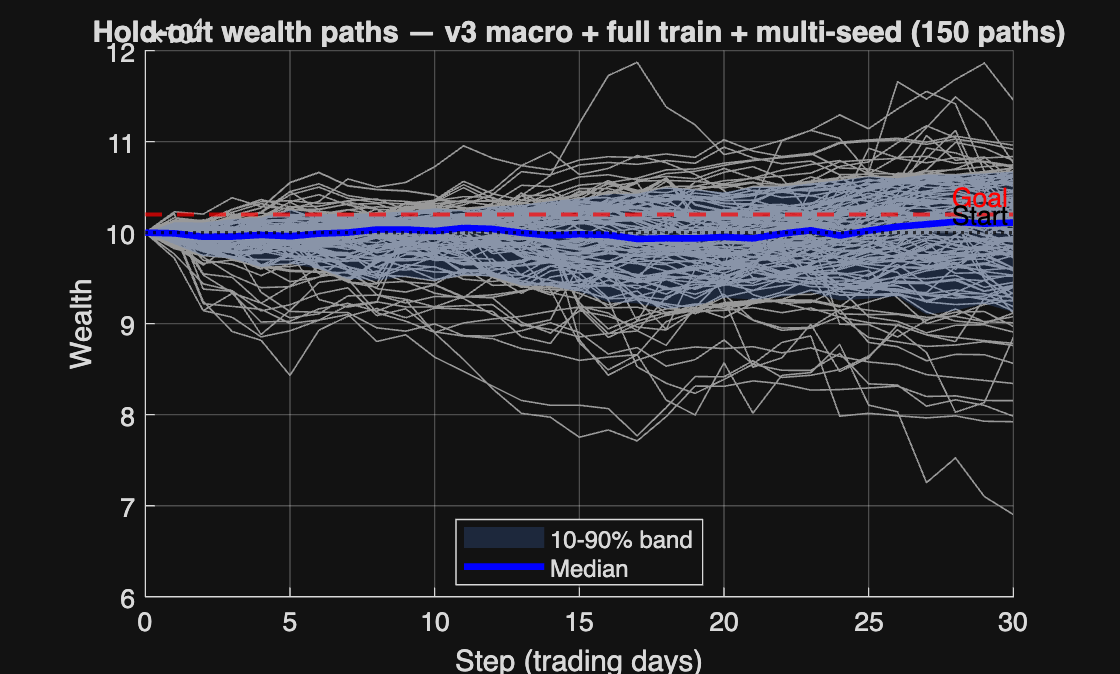

figure('Name','Hold-out wealth paths (multi-seed)');
hold on;

allPathsFlat = nan(nSeeds * numEvalEpisodes, horizonPeriods + 1);
rowCursor = 0;
for sIdx = 1:nSeeds
    paths = allWealthPathsBySeed{sIdx};
    for ep = 1:numel(paths)
        if ~isempty(paths{ep})
            rowCursor = rowCursor + 1;
            allPathsFlat(rowCursor, :) = paths{ep}';
        end
    end
end
allPathsFlat = allPathsFlat(1:rowCursor, :);

steps = 0:horizonPeriods;

for r = 1:size(allPathsFlat, 1)
    plot(steps, allPathsFlat(r, :), 'Color', [0.6 0.6 0.6 0.15], ...
        'LineWidth', 0.6, 'HandleVisibility', 'off');
end

p10 = prctile(allPathsFlat, 10, 1);
p90 = prctile(allPathsFlat, 90, 1);
fill([steps, fliplr(steps)], [p10, fliplr(p90)], [0.3 0.5 0.9], ...
    'FaceAlpha', 0.2, 'EdgeColor', 'none', 'DisplayName', '10-90% band');
plot(steps, median(allPathsFlat, 1, 'omitnan'), 'b-', 'LineWidth', 2.5, ...
    'DisplayName', 'Median');

yline(goalWealth, '--r', 'Goal', 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(initialWealth, ':k', 'Start', 'LineWidth', 1.2, 'HandleVisibility', 'off');

xlabel('Step (trading days)');
ylabel('Wealth');
title(sprintf('Hold-out wealth paths — v3 macro + full train + multi-seed (%d paths)', rowCursor));
legend('Location','best');
grid on;

## Local Functions

function [R, M_z] = inputTestData(priceFile, macroFile, macroMean, macroStd)
    pricesTT = readtable(priceFile, 'VariableNamingRule', 'preserve');
    P = pricesTT{:, 2:end};
    R = diff(log(P));

    macroTT = readtable(macroFile, 'VariableNamingRule', 'preserve');
    M = macroTT{:, 2:end};
    M_z = (M - macroMean) ./ macroStd;
end